1.Solve the ODE,

from t = 0 to 5 with y(0) = 0.08 using:

a. 4th order RK with constant step size of 0.03125.

b. Using Matlab’s ode45.

c. Using Matlab’s ode23s.

Note that all solutions diverge eventually.Use the stats parameter of the Matlab functions as well as tic toc to determine which one was more efficient at solving the equation then present your results in graphical form.

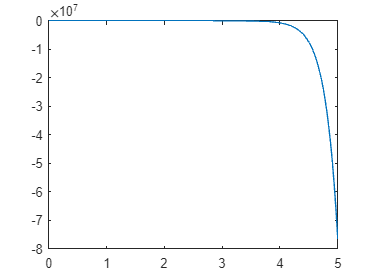

h = 0.03125; % step
t = 0:h:5;
y = 0.08;
func = @(t, y) 5.*(y - t.^2);

% a
y = eulerMethod(h, t, y, func);

plot(t, y);

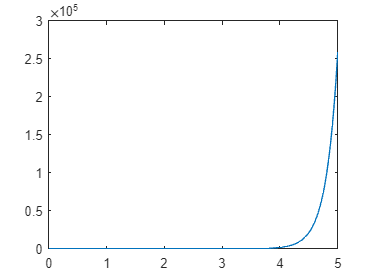


h = 0.03125; % step
t = 0:h:5;
y = 0.08;
func = @(t, y) 5.*(y - t.^2);

% b
[t, y] = ode45(func, t, y);
plot(t, y)

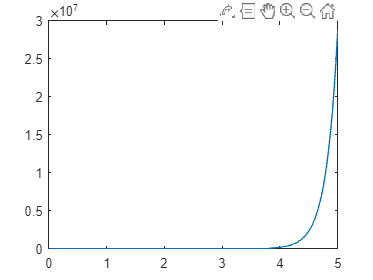


h = 0.03125; % step
t = 0:h:5;
y = 0.08;
func = @(t, y) 5.*(y - t.^2);
% c
[t, y] = ode23s(func, t, y);
plot(t, y)

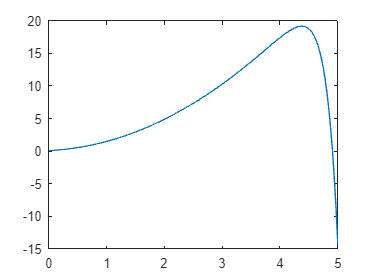



h = 0.03125; % step
t = 0:h:5;
y = 0.08;
func = @(t, y) 5.*(y - t.^2);
% d
[t, y] = ode23tb(func, t, y);
plot(t, y)

2.Convert the pendulum equation into a system of ODEs then solve using ode45.

where *g* is the gravitational constant = 9.81 m/s2, l is the length of the pendulum = 0.6 m, θ and *t* are the angle the pendulum makes with the horizontal and time respectively. Take the initial condition to be θ = π/2 and dθ/dt = 0 and solve for the first 10 seconds. Plot your results in a phase diagram with angle on the horizontal axis and angular velocity on the vertical axis.

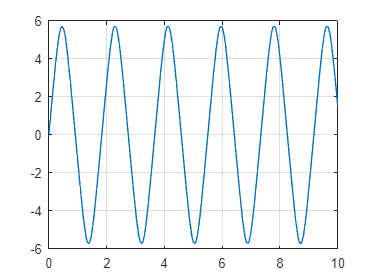

h = 0.1;
g = 9.81;
l = 0.6;

% Define the ODE system
ode = @(t, x) [x(2); (g/l) * sin(x(1))];

% Initial conditions
initial_conditions = [pi/2; 0];

% Time span for the simulation (0 to 10 seconds)
tspan = [0, 10];

% Solve the ODE system using ode45
[t, solution] = ode45(ode, tspan, initial_conditions);

% Extract the angle and angular velocity from the solution
theta = solution(:, 1);
omega = solution(:, 2);

% t vs angular velocity
figure;
plot(t, omega);
grid on;

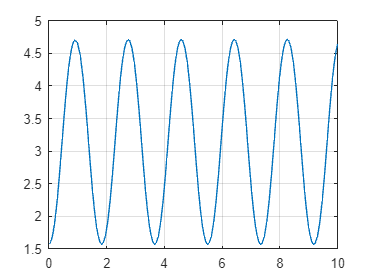


% t vs angle
figure;
plot(t, theta);
grid on;

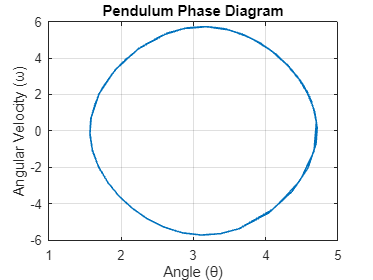


% Plot the results in a phase diagram
figure;
plot(theta, omega);
xlabel('Angle (θ)');
ylabel('Angular Velocity (ω)');
title('Pendulum Phase Diagram');
grid on;

3.Solve and plot the solution of the system (independent vs. dependent variables),

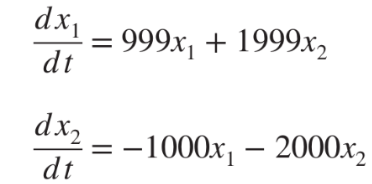

with x1(0) = x2(0) = 1 from t = 0 to 0.2 using a step size of h = 0.05 with:

a. The explicit (original) Euler method.

b. The implicit Euler method.

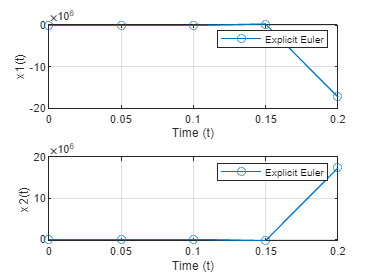

% Define the system of ODEs
ode = @(t, x) [999*x(1) + 1999*x(2); -1000*x(1) - 2000*x(2)];

% Initial conditions
x0 = [1; 1];

% Time span
tspan = [0, 0.2];

% Step size
h = 0.05;

% Number of time steps
N = (tspan(2) - tspan(1)) / h;

% Preallocate arrays for storing solutions
x_explicit = zeros(2, N+1);
x_implicit = zeros(2, N+1);

% Set initial conditions
x_explicit(:, 1) = x0;
x_implicit(:, 1) = x0;

% Explicit Euler method
for i = 1:N
    x_explicit(:, i+1) = x_explicit(:, i) + h * ode(tspan(1) + (i-1) * h, x_explicit(:, i));
end

% Implicit Euler method
for i = 1:N
    A = eye(2) - h * [999, 1999; -1000, -2000];
    b = x_implicit(:, i);
    x_implicit(:, i+1) = A\b;
end

% Time values for plotting
t = linspace(tspan(1), tspan(2), N+1);

% Plot the solutions (a)
figure;
subplot(2, 1, 1);
plot(t, x_explicit(1, :), '-o', 'DisplayName', 'Explicit Euler');
hold on;
xlabel('Time (t)');
ylabel('x1(t)');
legend;
grid on;

subplot(2, 1, 2);
plot(t, x_explicit(2, :), '-o', 'DisplayName', 'Explicit Euler');
hold on;
xlabel('Time (t)');
ylabel('x2(t)');
legend;
grid on;

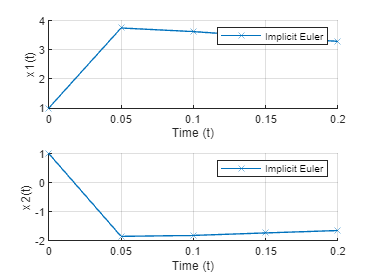


% Plot the solutions (b)
figure;
subplot(2, 1, 1);
hold on;
plot(t, x_implicit(1, :), '-x', 'DisplayName', 'Implicit Euler');
xlabel('Time (t)');
ylabel('x1(t)');
legend;
grid on;

subplot(2, 1, 2);
hold on;
plot(t, x_implicit(2, :), '-x', 'DisplayName', 'Implicit Euler');
xlabel('Time (t)');
ylabel('x2(t)');
legend;
grid on;

6.The linearised equation of motion of a pendulum is given by,

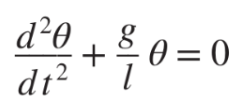

with initial angular velocity of 0. Taking *l* = 1 m, *g* = 9.81 m/s2, use the events parameter in Matlab to determine the period of the oscillation for:

a. θ = π/8 

ans: Period is approximately 2.005

c. θ = π/4

ans: Period is approximately 2.005

d. θ = π/2

ans: Period is approximately 2.005

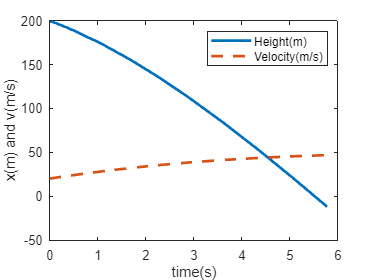

opts = odeset('events', @endevent);
y0 = [-200, 20];
[t, y, te, ye] = ode45(@freefall, [0, inf], y0, opts, 0.25, 68.1);
plot(t, -y(:,1), '-', t, y(:,2), '--', 'LineWidth', 2);
legend('Height(m)', 'Velocity(m/s)');
xlabel('time(s)');
ylabel('x(m) and v(m/s)');

te,ye

te = 5.7758

ye =    12.0000   46.8327



% (a)

% when use also need to change function below slide 14 page 20
opts = odeset('events', @periodevent);
y0 = [pi/8, 0];
[t, y, te, ye] = ode45(@oscillation, [0, inf], y0, opts, 1);
te, ye

te =     1.1067
    1.9021


ye =    -0.3722    0.3927
    0.3721    0.3927


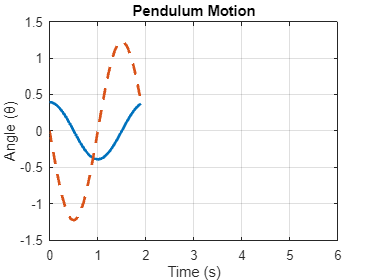


% omega positive
% Create a figure
figure;
theta = y(:,2);


% Plot the angle (θ) over time
plot(t, y(:,1), '-', t, y(:,2), '--', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Angle (θ)');
title('Pendulum Motion');
grid on;

% Limit the x-axis to the range [0, 6]
clear xlim;
xlim([0,6]);

function dydt = oscillation(t, y, l)
    g = 9.81;
    dydt = zeros(2, 1);
    % dydt = [y(2); (g/l) * y(1)];
    dydt(1) = y(2);
    dydt(2) = -(g/l)*y(1);
    
end

function [detect, stopint, direction] = periodevent(t, y, varargin)
    detect = y(2) - pi/8;
    stopint = 1;
    direction = 0;
    if y(2) >= pi/8
        stopint = 0;
    end
end


function y = eulerMethod(h, t, y, func)
        
    for i = 1:length(t)-1
        y(i + 1) = y(i) + (func(t(i), y(i)).* h);
    end
end

function dydt = freefall(t, y, cd, m)
    g = 9.81;
    dydt = [y(2); g-cd/m*y(2)*abs(y(2))];
end

function [detect, stopint, direction] = endevent(t, y, varargin)
    detect = y(1) - 12;
    stopint = 1;
    direction = 0;
end